function [mask, frameEdges] = mask_frames(stripImage)

Create a separate mask for each frame in an cartoon strip image Arguments: stripImage: cartoon strip image mask: mask with each pixel labelled with frame number frameEdges: column where the edge of the frames are The first column is automatically a frame boundary

Note the number of frames is the length of frameEdges plus one, or the largest value in mask.

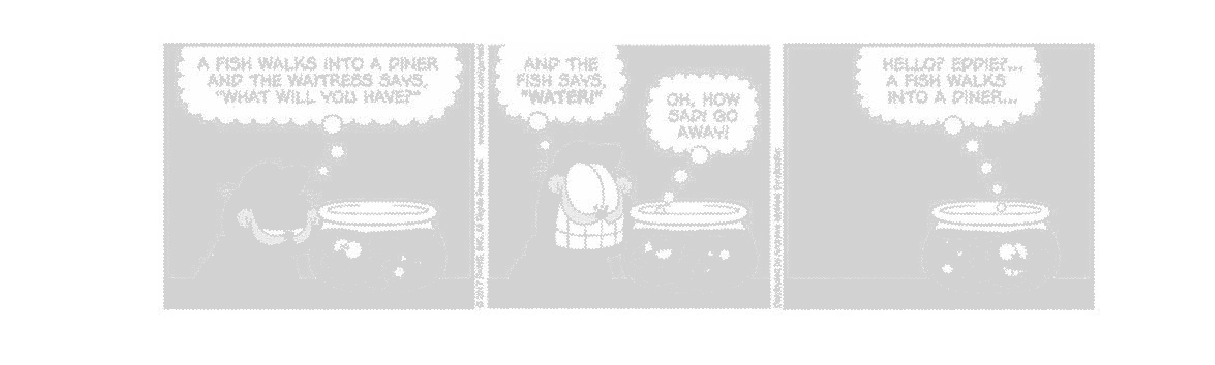

% function [mask, frameEdges] = mask_frames(stripImage)
stripImage=rotatedImages{imageNumber};

localImage=im2double(rgb2gray(stripImage));
imageWidth=size(localImage,2);

% Convert everything below median to median
% This removes black borders; only white boundaries are significant
thresh=median(localImage,'all');
localImage(localImage<thresh)=thresh;
image_show_resize(localImage);

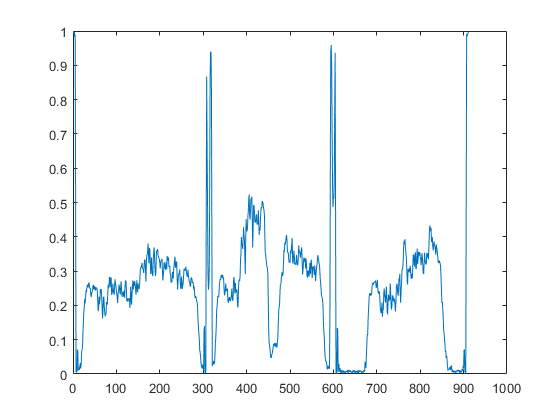


% Take the vertical mean
vertMean=rescale(mean(localImage,1));
figure, plot(vertMean);

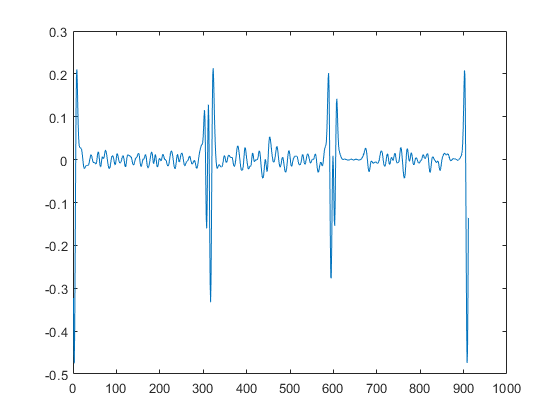


% Create Gaussian filters
sigma2=round(imageWidth/81);
width1=3*sigma2;
h=gausswin(2*width1,sigma2);
hd1=diff(h);
hd2=diff(hd1);hd2=hd2/sum(abs(hd2));

% Filter with second derivate of Gaussian
% Peaks of second derivative are rapid transitions black-white-black (negative) or
% white-black-white (positive)
vertImage=conv(vertMean,hd2,'same');
figure, plot(vertImage);

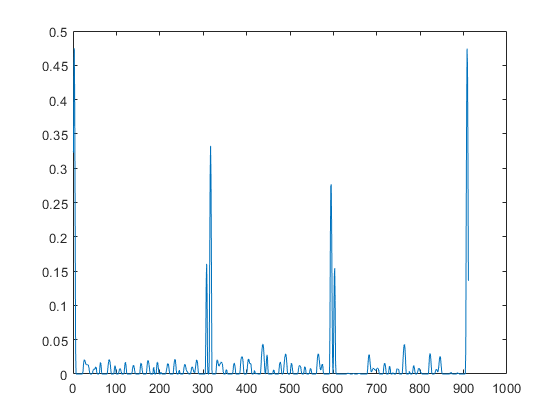


% White peaks are negative, so invert and truncate
vertImage=-vertImage;
vertImage(vertImage<0)=0;
figure, plot(vertImage);

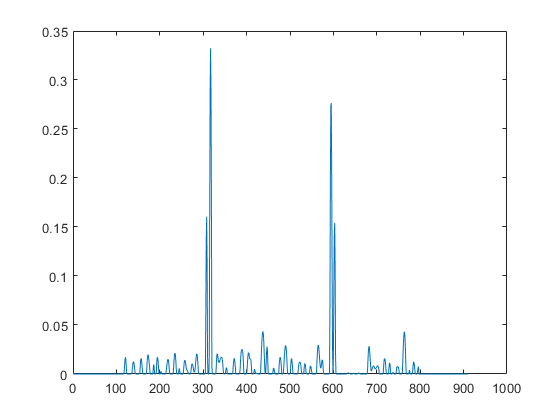


% Peaks near ends of the image aren't frame boundaries, so
% remove them from further processing
vertImage(:,1:ceil(0.125*imageWidth))=0;
vertImage(:,floor(0.875*imageWidth):end)=0;
figure, plot(vertImage);

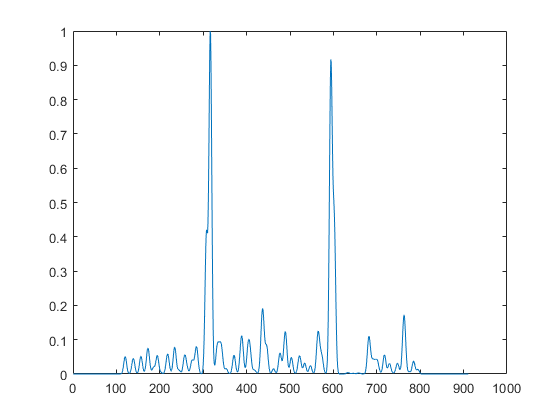


% Filter the result with a Gaussian window. This merges peaks that are
% close together
vertImage=conv(vertImage,h,'same');
vertImage=rescale(vertImage);
figure, plot(vertImage);

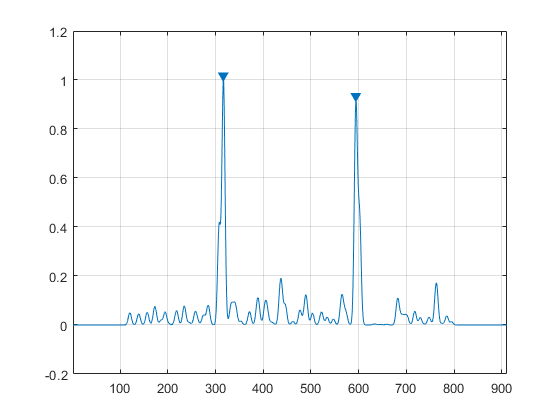


% Find the peaks
[~,frameEdges] = findpeaks(vertImage,...
    'MinPeakProminence',0.5,'MinPeakDistance',width1);

% Repeat the call to only display the image
findpeaks(vertImage,...
    'MinPeakProminence',0.5,'MinPeakDistance',width1);

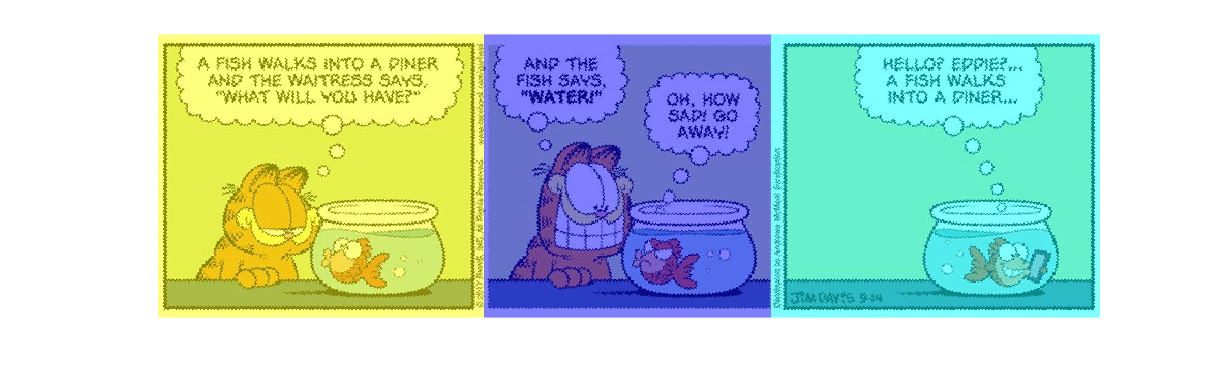


% Create a mask for each frame
frameMask = uint8(ones(size(localImage)));
for f=1:length(frameEdges)
    frameMask(:,frameEdges(f):end)=f+1;
end

% Put a zero as the first frame 'edge' and the width of the image as the
% end of the last frame.
frameEdges=[0 frameEdges imageWidth];

image_show_resize(labeloverlay(stripImage,frameMask));